Experimenting with the fit calculation for in vivo data

%row = dat2(1,:);
row = dat2_kin(1,:);
t_end = find(row.t{1} >= 250,1);
bio = row.biomass{1}(1:t_end);
t = row.t{1}(1:t_end);
y_calc = bio\t;
[pf,S] = polyfit(t,bio,3);
[y_fit,delta] = polyval(pf,ivd.denhaan.ctdat,S);
%     hold on;
%     plot(t,bio,t,y_fit);
%     plot(t,y_fit+2*delta,'m--',t,y_fit-2*delta,'m--');
%     hold off;
gdw = ivd.denhaan.gdw;
res = ivd.denhaan.gdw - polyval(pf,ivd.denhaan.ctdat,S);
%plot(res)
r2 = 1 - sum((gdw - y_fit).^2)/sum((gdw - mean(y_fit)).^2);
rs(1) = r2;
ssrs(1) = sum((gdw - y_fit).^2);


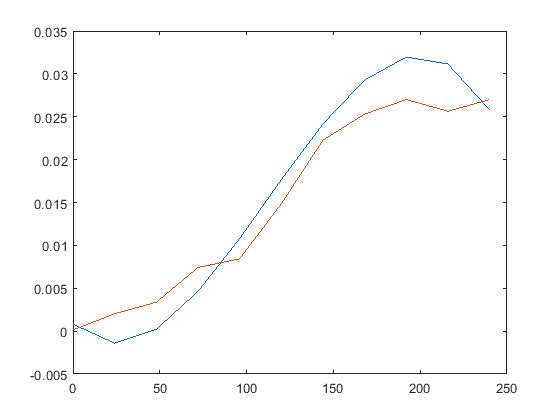

yhat = (pf(1) * x.^3) + (pf(2) * x.^2) + (pf(3) * x) + pf(4);
plot(x,yhat,x,gdw);